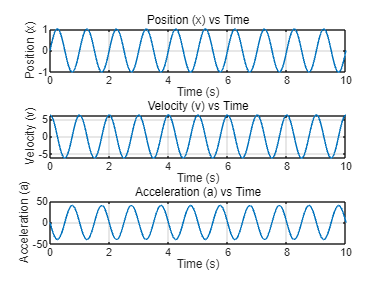

% 초기 변수 설정
A = 1;        % 진폭 (Amplitude)
omega = 2*pi; % 각속도 (Angular frequency, rad/s)
phi = 0;      % 위상 (Phase, rad)
t = 0:0.01:10; % 시간 (Time, sec)

% 단순 조화 운동 방정식 (위치, 속도, 가속도)
x = A * sin(omega * t + phi);       % 위치
v = A * omega * cos(omega * t + phi); % 속도
a = -A * omega^2 * sin(omega * t + phi); % 가속도

% 그래프 그리기
figure;
subplot(3,1,1); 
plot(t, x);
title('Position (x) vs Time');
xlabel('Time (s)');
ylabel('Position (x)');
grid on;

subplot(3,1,2); 
plot(t, v);
title('Velocity (v) vs Time');
xlabel('Time (s)');
ylabel('Velocity (v)');
grid on;

subplot(3,1,3); 
plot(t, a);
title('Acceleration (a) vs Time');
xlabel('Time (s)');
ylabel('Acceleration (a)');
grid on;

- `A`는 진폭(Amplitude), `omega`는 각속도(Angular frequency), `phi`는 위상(Phase)를 나타냅니다.

- `x`는 시간 `t`에 따른 위치, `v`는 속도, `a`는 가속도를 계산합니다.

- 각 그래프는 시간에 따른 위치, 속도, 가속도의 변화를 보여줍니다.

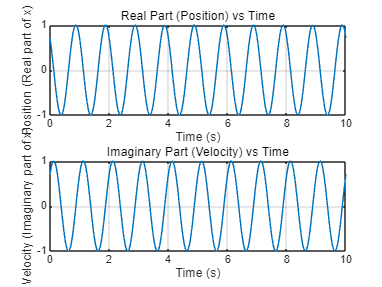

% 초기 변수 설정
A = 1;        % 진폭 (Amplitude)
omega = 2*pi; % 각속도 (Angular frequency)
phi = pi/4;   % 위상 (Phase, rad)
t = 0:0.01:10; % 시간 (Time, sec)

% 복소수 표현을 이용한 단순 조화 운동
x_complex = A * exp(1i*(omega*t + phi)); % 복소수 표현

% 실수부와 허수부 구하기
x_real = real(x_complex); % 실수부
x_imag = imag(x_complex); % 허수부

% 그래프 그리기
figure;
subplot(2,1,1);
plot(t, x_real);
title('Real Part (Position) vs Time');
xlabel('Time (s)');
ylabel('Position (Real part of x)');
grid on;

subplot(2,1,2);
plot(t, x_imag);
title('Imaginary Part (Velocity) vs Time');
xlabel('Time (s)');
ylabel('Velocity (Imaginary part of x)');
grid on;

- **복소수 표현**:

- 
$$x = a + ib = A (\cos \phi + i \sin \phi) = A e^{i \phi}$$


- 이는 오일러 공식을 사용한 복소수 표현입니다. 여기서 $A = \sqrt{a^2 + b^2}, \phi = \tan^{-1} \left( \frac{b}{a} \right)$로 표현됩니다.

- **복소수에서 회전 벡터의 미분**:

- 복소수 표현에서 운동 방정식을 미분하여 위치, 속도, 가속도를 구할 수 있습니다.

- $x(t) = A \sin(\omega t) = \Im[x]$ (위치)

- $\dot{x}(t) = A \omega \cos(\omega t) = A \omega \sin(\omega t + \frac{\pi}{2}) = \Im[\dot{x}]$ (속도)

- $\ddot{x}(t) = -A \omega^2 \sin(\omega t) = A \omega^2 \sin(\omega t + \pi) = \Im[\ddot{x}]$ (가속도)

**정의된 파라미터:**

- **진동 진폭 (Amplitude)**: 진동의 최대 크기.

- **진동 주기 (Period of oscillation)**: $\tau = \frac{2\pi}{\omega}$�, 주기는 한 번의 진동이 끝나는 시간을 의미합니다.

- **진동주파수 (Frequency of oscillation)**:$f = \frac{1}{\tau} = \frac{\omega}{2\pi}$�, 1초 동안 몇 번의 진동이 발생하는지를 나타냅니다.

- **위상 각 (Phase angle)**: 진동의 시작 위치나 시간에 따른 위상 변화를 나타냅니다.

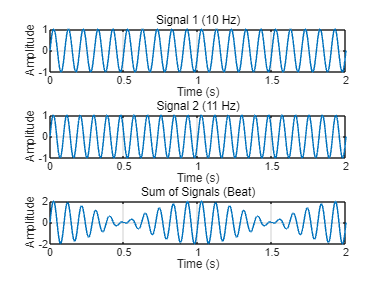

% 초기 변수 설정
A = 1;         % 진폭 (Amplitude)
f1 = 10;       % 첫 번째 주파수 (Hz)
f2 = 11;       % 두 번째 주파수 (Hz)
t = 0:0.001:2; % 시간 (Time, seconds)

% 두 개의 신호 생성
x1 = A * sin(2 * pi * f1 * t); % 첫 번째 신호
x2 = A * sin(2 * pi * f2 * t); % 두 번째 신호

% 두 신호의 합 (맥놀이)
x_sum = x1 + x2;

% 그래프 그리기
figure;
subplot(3,1,1);
plot(t, x1);
title('Signal 1 (10 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, x2);
title('Signal 2 (11 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t, x_sum);
title('Sum of Signals (Beat)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

- **고유 진동수 (Natural Frequency)**:

- 외부 힘 없이 시스템이 진동하는 빈도입니다.

- **맥놀이 현상 (Beat Phenomenon)**:

- 두 개의 유사한 주파수를 가진 진동이 겹쳐질 때, 진동이 상호 간섭하여 시간에 따라 진폭이 주기적으로 변하는 현상을 의미합니다.

- 두 신호 $x_1(t) = X \sin(\omega t)$와 $x_2(t) = X \sin((\omega + \Delta\omega) t)$가 더해지면 맥놀이가 발생합니다.

- 결과적으로 시간에 따라 변하는 진폭과 고유한 진동 패턴이 나타납니다: $x(t) = 2X \sin \left( \frac{\Delta\omega}{2} t \right) \cos \left( \frac{2\omega + \Delta\omega}{2} t \right)$

- **맥놀이 주기 (Beat Period)**:

- 맥놀이 주기 $\tau_b = \frac{2\pi}{\Delta\omega}$�는 두 주파수 간 차이에 따라 결정됩니다.

- $\tau_b$�는 맥놀이 현상이 완전히 한 주기 도는 데 걸리는 시간을 의미합니다.

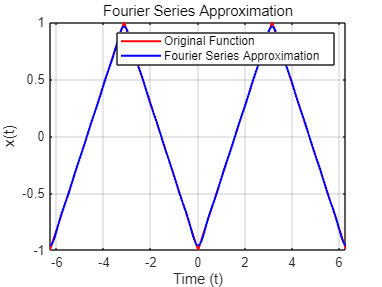

% 초기 변수 설정
L = pi; % 주기 (Period)
x = @(t) sawtooth(t, 0.5); % 예시 함수 (톱니파)

% 시간 범위 설정
t = -2*L:0.01:2*L; 

% 푸리에 급수 계수 계산
N = 10; % 푸리에 급수 항 수
a0 = (1/(2*L)) * integral(@(t) x(t), -L, L); % 상수항 a0
sum_f = a0/2; % 푸리에 급수 초기화

% 푸리에 급수 계산
for n = 1:N
    an = (1/L) * integral(@(t) x(t).*cos(n*pi*t/L), -L, L);
    bn = (1/L) * integral(@(t) x(t).*sin(n*pi*t/L), -L, L);
    sum_f = sum_f + an*cos(n*pi*t/L) + bn*sin(n*pi*t/L);
end

% 그래프 그리기
figure;
plot(t, x(t), 'r', 'LineWidth', 1.5); hold on;
plot(t, sum_f, 'b', 'LineWidth', 1.5);
title('Fourier Series Approximation');
xlabel('Time (t)');
ylabel('x(t)');
legend('Original Function', 'Fourier Series Approximation');
grid on;

- **조화 해석 (Harmonic Analysis)**:

- 여러 진동 시스템에서의 움직임을 설명합니다.

- 단순히 조화 운동은 아니지만, **주기 함수(periodic)**로 푸리에 급수를 이용해 사인과 코사인 함수의 합으로 표현할 수 있습니다.

- **푸리에 급수 (Fourier Series)**:

- **주기 함수**$X(t)$를 주기 $\tau$로 표현할 수 있습니다.

- 푸리에 급수 식: $x(t) = \frac{a_0}{2} + \sum_{n=1}^{\infty} \left( a_n \cos n\omega_0 t + b_n \sin n\omega_0 t \right)$

- 기본 주파수 $\omega_0 = \frac{2\pi}{\tau}$�.

- **계수 계산**:

- 
$$a_0 = \frac{2}{\tau} \int_0^\tau x(t) dt$$


- 
$$a_n = \frac{2}{\tau} \int_0^\tau x(t) \cos n\omega_0 t dt$$


- 
$$b_n = \frac{2}{\tau} \int_0^\tau x(t) \sin n\omega_0 t dt$$


- **정리된 표현**:

- 위의 식을 정리하면: $x(t) = \frac{a_0}{2} + \sum_{n=1}^{\infty} C_n \sin(n\omega_0 t + \psi_n)$

- 여기서 $C_n = \sqrt{a_n^2 + b_n^2}$이고, 위상각 $\psi_n = \tan^{-1}\left(\frac{b_n}{a_n}\right)$입니다.

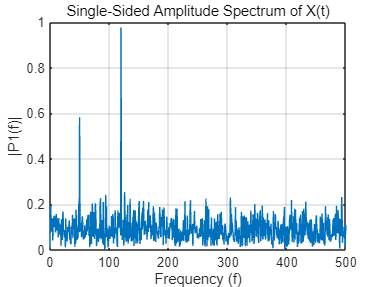

% 초기 변수 설정
Fs = 1000;         % 샘플링 주파수 (Hz)
T = 1/Fs;          % 샘플링 간격
L = 1500;          % 샘플 수
t = (0:L-1)*T;     % 시간 벡터

% 신호 생성: 주파수가 다른 두 사인파 합성
S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);

% 신호에 약간의 잡음을 추가
X = S + 2*randn(size(t));

% 푸리에 변환
Y = fft(X);

% 주파수 성분 계산
P2 = abs(Y/L);        % 푸리에 변환 후 절댓값 계산
P1 = P2(1:L/2+1);     % 대칭성을 이용한 단측 스펙트럼
P1(2:end-1) = 2*P1(2:end-1);

% 주파수 축 계산
f = Fs*(0:(L/2))/L;

% 그래프 그리기
figure;
plot(f, P1);
title('Single-Sided Amplitude Spectrum of X(t)');
xlabel('Frequency (f)');
ylabel('|P1(f)|');
grid on;

- **주파수 스펙트럼 (Frequency Spectrum)**:

- 주기 함수 $x(t)$의 **n번째 고조파(Harmonics)** 성분을 나타냅니다.

- $a_n \cos(n\omega_0 t) + b_n \sin(n\omega_0 t)$을 조화적으로 정리하면 $C_n \sin(n\omega_0 t + \psi_n)$로 변환할 수 있습니다.

- 여기서 $C_n$�은 진폭, $\psi_n$�은 위상각을 나타냅니다.

- 주파수 스펙트럼은 주파수 영역에서 특정 주파수의 성분을 시각화한 것입니다. 각 고조파는 특정 주파수에 해당하는 스파이크로 나타납니다.

- **시간 영역(Time Domain)과 주파수 영역(Frequency Domain) 표현**:

- 시간 영역에서의 신호는 시간에 따른 함수로 표현됩니다. 예시로 $x(t) = A \sin(\omega t + \phi)$가 주어졌습니다.

- 주파수 영역에서는 시간의 개념을 없애고 신호가 포함된 주파수 성분을 나타냅니다. 예를 들어 단일 사인파는 주파수 영역에서 하나의 특정 주파수 성분으로 나타납니다.

- **시간 영역과 주파수 영역에서의 신호 표현**:

- 사각파나 톱니파 같은 복잡한 주기 신호는 시간 영역에서 불연속적인 변화가 보일 수 있습니다.

- 이 신호는 푸리에 변환을 통해 주파수 영역에서 여러 주파수 성분으로 분해됩니다.